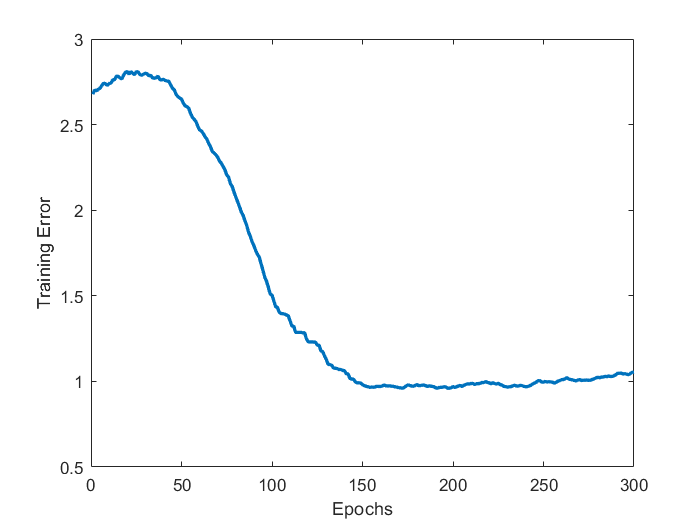

rng(1)

Epochs = 200;

error = zeros(1,Epochs);
error(1) = 2.678;
for i = 2:100
    error(i) =  error(i-1) - i^1.2/10000 + rand(1)/(i+10) - rand(1)*(i+150)/10550;
end


nn = 24;
for i = 100:150
    error(i) = error(i-1) - (rand()^4)/nn ;
end

nn = 100;
for i = 150:300
    error(i) = error(i-1) - (rand(1) - rand(1))/nn ;
end



plot(error, 'LineWidth', 2);
xlabel('Epochs');
ylabel('Training Error');

%title('Training Error Reduction with Experience Replay');